# Documentation: Box model of the carbon cycle and zero-dimensional model fo the climate

The seven-box model of the carbon cycle and a zero-dimensional model of the climate are combined hereinafter. The carbon cycle model defines seven boxes representing different components of the Earth system, including the atmosphere, surface ocean, intermediate ocean, deep ocean, sediment, biosphere, and soil. The model simulates the exchange of carbon among these boxes over time, using historical data and predictions for future emissions from fossil fuel combustion and land-use changes.

The code reads in historical data on carbon emissions from fossil fuels and land-use changes, as well as predictions for these emissions based on different scenarios. The mclimate model incorporates the carbon cycle model and solar irradiance data and calculates the change in global temperature over time based on a feedback system. 

clearvars;close all;clc;
set(0, 'DefaultFigureRenderer', 'painters');
% box 1 = atmosphere
% box 2 = surface ocean
% box 3 = intermediate ocean
% box 4 = deep ocean
% box 5 = sediment
% box 6 = biosphere
% box 7 = soil
Nbox = 7;

% Define time step and simulation duration
dt = 1; % Time step (unit:yr)
tmax = 300; % Simulation duration (yr)
t = 1750 + [0:dt:350];
N = numel(t);

## Load emissions data (historical)

% Emissions from Fossile fual and industry
clf;close all
load('gamma_ourWorldInData.mat','Year','Total')
Total_fossileFuel = Total*3/11*1e6/1e15;

% Emissions from land use change
load('delta_ourWorldInData.mat','year','Land_use_change')
Land_use_change = Land_use_change*3/11*1e6/1e15;


## Load emissions data (predictions)

Data are interpolated onto a  new time array

Tab = readtable('ipcc-scenarios.csv');


scenario = {'SSP1 - Baseline','SSP2 - Baseline','SSP3 - Baseline','SSP4 - Baseline','SSP5 - Baseline'};

gamma = zeros(numel(scenario),numel(t));
delta = zeros(numel(scenario),numel(t));
for pp= 1:numel(scenario),
    indS = find(contains(Tab{:,1},scenario(pp)));
    CO2_prediction_fossil = Tab.FossilCO2Emissions(indS)*3/11*1e6/1e15;
    CO2_prediction_land = Tab.LandCO2Emissions(indS)*3/11*1e6/1e15;
    t_prediction = Tab.Year(indS);


    [tp,ind,IB] = unique([Year(~isnan(Year))',t_prediction']);
    C_ff = [Total_fossileFuel(~isnan(Year))',CO2_prediction_fossil'];
    C_ff = C_ff(ind);
    gamma(pp,:) = interp1(tp,C_ff,t,'pchip');


    [tp,ind,IB] = unique([year(~isnan(year))',t_prediction']);
    C_luc = [Land_use_change(~isnan(year))',CO2_prediction_land'];
    C_luc = C_luc(ind);
    delta(pp,:) = interp1(tp,C_luc,t,'pchip');
    indMin = find(t<min(tp));
    delta(pp,indMin) = C_luc(1); % extrpolation for earliest time
end

## Visualize emissions (historical and predicted)

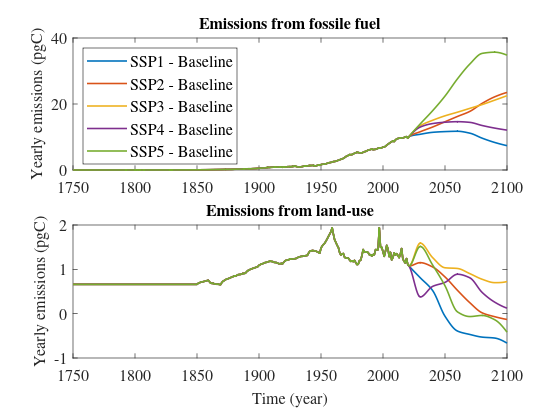

clf;close all;
figure
tiledlayout(2,1,"TileSpacing","tight")
nexttile
plot(t,gamma,'linewidth',1.2);
% xlabel('Time (year)')
ylabel('Yearly emissions (pgC)')
set(gcf,'color','w')
title('Emissions from fossile fuel')
legend(scenario{:},'location','northwest')

nexttile
plot(t,delta,'linewidth',1.2);
xlabel('Time (year)')
ylabel('Yearly emissions (pgC)')
set(gcf,'color','w')
title('Emissions from land-use')

set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

## Get solar irradiance data 

Source: [https://lasp.colorado.edu/lisird/data/nrl2_tsi_P1Y](https://lasp.colorado.edu/lisird/data/nrl2_tsi_P1Y) 

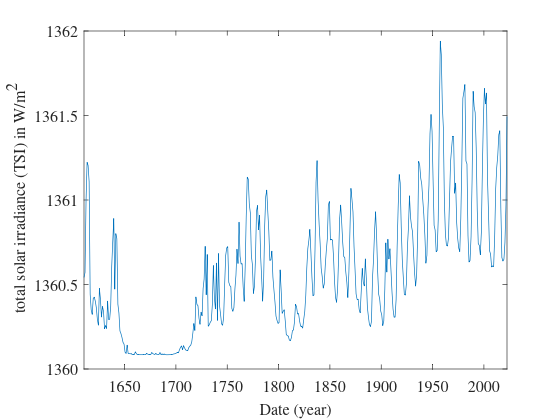

tsi = double(ncread('tsi_v02r01_yearly_s1610_e2022_c20230120.nc','TSI'));
time = days(ncread("tsi_v02r01_yearly_s1610_e2022_c20230120.nc",'time')) + datetime(1610,1,1);

figure
plot(time,tsi)
xlabel('Date (year)')
ylabel(' total solar irradiance (TSI) in W/m^2')
set(gcf,'color','w')

set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

## Get Atmospheric CO2 concentrations

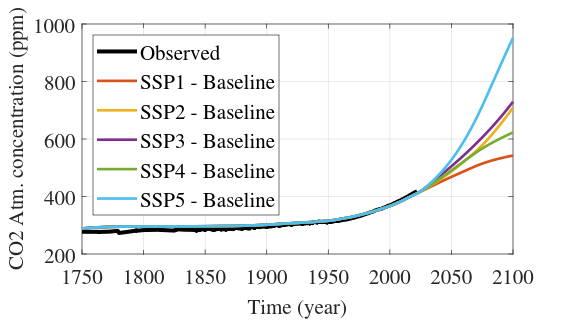

C_CO2 = nan(numel(scenario),numel(t));
for pp= 1:numel(scenario),
    [dummy] = run7Box(t,gamma(pp,:),delta(pp,:));
    C_CO2(pp,:) = dummy(1,:); % atmospheric CO2 concentration
end

clf;close all;figure('position',[500 620         634         358])
grid on
m = readtable('climate-change.csv', "Range" , [846 2 2777 3]); %dlmread
plot(m{:,1},inpaint_nans(m{:,2},4),'k','linewidth',3)
hold on
plot(t, C_CO2,'LineWidth',2);
xlim([1750 2100])
legend('Observed',scenario{:},'location','northwest')
xlabel('Time (year)')
grid on
ylabel('CO2 Atm. concentration (ppm)')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',16,'FontName','Times')

## Change in global temperatures

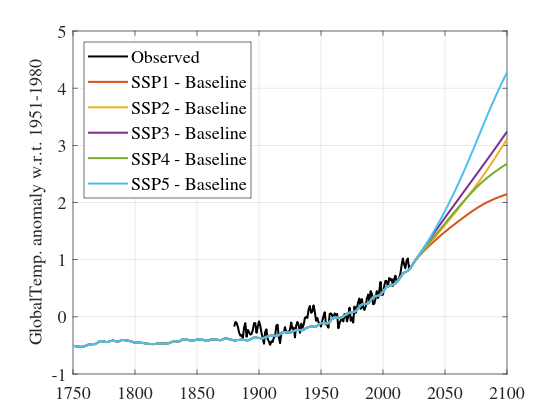

clear Year year
t1 = years(t) + datetime(0,1,1,15,0,0);
% Interpolate solar irradiance onto new vector
S = interp1(time,tsi,t1,'nearest','extrap');% in W m^-2  --- Solar irradiance at the top of the atmosphere
alpha = 0.31; % albedo
C = 2.1e8; % total heat capacity ocean + atm in J K-1 m-2
a = 3.7./log(2) ; % c in W m^-2
% Preallocate temperature
T0 = 14+273.15; % pre industrial temperature 
T=T0.*ones(numel(scenario),N); % Initialisation
B = -1.3; % climate feedback in W m^-2 K^-1, negative for stabilization effect
A = S(1).*(1-alpha)/4 + B.*T0; % Initial value
for pp= 1:numel(scenario),
    for ii=1:N-1
        % Q = Incoming solar radiation - outgoing thermal radiation
         Q = S(ii).*(1-alpha)/4 - A + B.*T(pp,ii); % W m-2
        % Forcing from anthropogenic emissions (Myhre et al, 1998)
        F_CO2 = a.*log(C_CO2(pp,ii)./C_CO2(pp,1));
        % We need to convert Watt-year into  Joule as C is expressed in joules
        coeff = 8760*3600; 
        % Global temperature  from Earth's planetary energy balance
        T(pp,ii+1) = coeff.*(Q + F_CO2).*dt./C+ T(pp,ii) ;
    end
end

clf;close all;
load('T_anomaly_1850.mat','t_obs','T_obs') % Load temperature anomaly (from NASA)
[~,indStart]=min(abs(t-1951));
[~,indEnd]=min(abs(t-1980));
figure
plot(t_obs,T_obs,'linewidth',1.5,'color','k');
hold on
plot(t,T-mean(T(:,indStart:indEnd),2),'linewidth',1.5);
grid on
ylabel('GlobalTemp. anomaly w.r.t. 1951-1980')
legend('Observed',scenario{:},'location','northwest')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

## Temperature increaste w.r.t PI value

Code inspired by [https://computationalthinking.mit.edu/Fall20/lecture20/](https://computationalthinking.mit.edu/Fall20/lecture20/) 

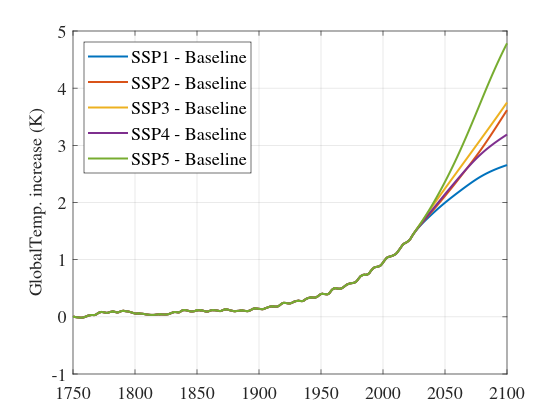

clf;close all;
figure
% plot(t_obs,T_obs-mean(T_obs(1:25)),'linewidth',1.5,'color','k');
% hold on
plot(t,T-T0,'linewidth',1.5);
grid on
ylabel('GlobalTemp. increase (K)')
legend(scenario{:},'location','northwest')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')